# BDX Droid Long Jump

Run bdx droid (Serial chain - joints are connected in sequence)

arc-bridge branch name = altmands

droid index = 0 (droid)

First run arc-bridge with the option --block to wait for control command

Run this matlab script

remember to generate the lcm messages: rabbit_state_t & rabbit_control_t

Direct Collocation is done in matlab and sent to arc-bridge for visualization

clc; clear; 
run setup.m

Setup Success!



% Setup LCM protocol
lcm_cmd_topic = "bdx_droid_control";
lcm_state_topic = "bdx_droid_state";
lc = lcm.lcm.LCM.getSingleton();
getenv("LCM_DEFAULT_URL")


ans =

  0×0 empty char array




aggregator = lcm.lcm.MessageAggregator();
aggregator.setMaxMessages(1);
lc.subscribe(lcm_state_topic, aggregator);

control_freq = 500; % control frequency in Hz (how frequently messages are sent through LCM)
rate_ctrl = rateControl(control_freq);
dt_ctrl = 1 / control_freq; % different from optimization dt
steps = 10000; % Tot steps for the simulation

% parameters - adjust these possibly for the BDXDroid
% Initial state for the LCM loop (optional but good to do)
rs.qb = [0.0; 0.4];
rs.dqb = [0.5; 0.0];
rs.pf = [-0.04, 0.0; 0.04, 0.0]; % foot positions (left and right)

p.g = 9.81;
p.l = [0.2, 0.4, 0.4]';
p.M = [10 1 0.5]';
p.I = [0.01 0.005 0.005]';
p.params = [p.g; p.l; p.M; p.I];
p.mu = 1;
p.alpha = 0.5;

p.l0 = 0.24;
p.k = 2000; % Increased stiffness for better jump
p.c = 10; % Damping coefficient
p.Q_tor = [1 1 1]';
p.Q_f = repmat([1 1]',[2,1]);

Kp = diag([200,200,200,200]);
Kd = diag([20,20,20,20]);
import casadi.*

% Optimization params
p.N = 50; % Number of collocation steps (51 collocation points)
ds = 1/p.N;
Umax_val = 1500 % max force output (N)

Umax_val = 1500

thmax = 1;
% Boundary Conditions for a single jump: state X = [x:z;dx;dz] which is for
% the torso
X0 = [0.0;p.l0;1.0;0.0];
Xf = [1.0;p.l0;0.0;0.0];

opti = casadi.Opti();
X = opti.variable(4,p.N+1);
U = opti.variable(2,p.N+1);
tf = opti.variable(1,1);
dt_optm = tf * ds;

obj = MX(0);
opti.subject_to(X(:,1) == X0);

opti.subject_to(X(2,end) == p.l0);
opti.subject_to(X(3, end) <= 0.2); % dx adjustment
opti.subject_to(X(4, end) <= 0.1); % dz adjustment

opti.subject_to(X(1,end) >= 0.4); % enforce min jumping distance of 0.4m


opti.subject_to(0.2 <= tf);
opti.subject_to(tf <= 1.2); % enough time to land

% Loop for constraints (Trapezoid collocation)
for kk = 1:p.N
    Xk = X(:,kk);
    Uk = U(:,kk);
    Xkp1 = X(:,kk+1);
    Ukp1 = U(:,kk+1);

    % Objective contribution
    obj = obj + 0.1 * Uk'*Uk;                      % input expenditure
    obj = obj + 0.01 * (Ukp1-Uk)' * (Ukp1-Uk);      % input smoothness
   
    % Dynamic Constraint
    fk = dynamics_SLIP(Xk,Uk,p);
    fkp1 = dynamics_SLIP(Xkp1,Ukp1,p);
    opti.subject_to(Xkp1 == Xk + (0.5)*dt_optm*(fk + fkp1));

    % Path constraints
    % opti.subject_to(Uk(2) >= 0);
    % opti.subject_to(-p.mu * Uk(2) <= Uk(1));
    % opti.subject_to(Uk(1) <= p.mu * Uk(2));
    opti.subject_to(Uk(1)^2 + Uk(2)^2 <= Umax_val^2); % Fx^2 + Fz^2 <= Umax^2
    opti.subject_to(Xk(2) >= p.l0 * 0.5);

end
obj = obj + 50 * tf^2;
obj = obj - 500 * X(1,end); % reduction of distance award
obj = obj + 100 * X(4,end)^2; % Penalty for hard landing

opti.minimize(obj);

% Solve and find optimal trajectory
opti.set_initial(tf,0.1); % initial guess for flight time is 0.5
opti.solver('ipopt');
sol = opti.solve();

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     1005
Number of nonzeros in inequality constraint Jacobian.:      155
Number of nonzeros in Lagrangian Hessian.............:      408

Total number of variables............................:      307
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      205
Total number of inequality constraints...............:      105
        inequality constraints with only lower bounds:       52
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:       53

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  5.0000000e-01 1.00e+00 1.55e-03  -1.0 0.00e+00    -  0.00e+00 0.00e+00 


Xout = sol.value(X);
Uout = sol.value(U);
tf_val = sol.value(tf)

tf_val = 0.9995

dt_val = tf_val / p.N;
tout = linspace(0,tf_val,p.N+1);
fprintf(' Optimization Results\n');

 Optimization Results


fprintf('Final state from optimization:\n');

Final state from optimization:


fprintf('x: %.3f, z: %.3f, dx: %.3f, dz: %.3f\n', Xout(1,end), Xout(2,end), Xout(3,end), Xout(4,end));

x: 0.662, z: 0.240, dx: 0.200, dz: -2.290



% Plot just the optimized trajectory
figure;
plot(Xout(1,:), Xout(2,:), 'r-o', 'LineWidth', 2);
xlabel('x [m]'); ylabel('z [m]');
title('Optimized SLIP Trajectory');
grid on;

fprintf('Jump time: %.3f s\n',tf_val);

Jump time: 1.000 s


fprintf('Jump distance: %3f m\n',Xout(1,end));

Jump distance: 0.661804 m


fprintf('Max height: %.3f m\n',max(Xout(2,:)));

Max height: 0.578 m


fprintf('Max force: %.1f N\n',max(sqrt(Uout(1,:).^2 + Uout(2,:).^2)));

Max force: 162.9 N




% Xdebug = opti.debug.value(X);
% Udebug = opti.debug.value(U);
% tfdebug = opti.debug.value(tf);
% disp('Last X:'); disp(Xdebug);
% disp('Last U:'); disp(Udebug);
% disp('Last tf:'); disp(tfdebug);
% tfv = opti.debug.value(tf);
% dtv = opti.debug.value(dt);
% fprintf('tf = %.4f, dt = %.4f, N = %d, dt*N = %.4f\n', tfv, dtv, p.N, dtv*p.N);

%% Real-Time Execution Loop (Main Loop)

fprintf("\n Starting LCM control loop \n")


 Starting LCM control loop 



rs2DSLIP = init2DSLIPState(rs,p);
state_history = zeros(steps,12);
fprintf('hi\n')

hi


for k = 1:steps
    
    msg = aggregator.getNextMessage(0);
    t = (k - 1) * dt_ctrl;
    if isempty(msg)
        continue
    end
    
    lc_state = eval("lcm_msgs."+lcm_state_topic+"_t(msg.data)");
    lc_cmd = eval("lcm_msgs."+lcm_cmd_topic+"_t()");

    % Update the SLIP simulation
    rs2DSLIP = update2DSLIPState(rs2DSLIP,p,dt_ctrl,k);
    
    if t <= tf_val

        [~,plan_idx] =  min(abs(tout - t)); % plan_idx closest collocation point
        plan_idx = min(plan_idx,p.N+1);

    else
        plan_idx = p.N + 1; % Holds final reference state 

    end
        

    Xref = Xout(:,plan_idx);

    % Publish joint torque command to LCM    
    
    % Most use the optimal plan Xref not the local simulated state
    % lc_cmd.se_pos = [rs2DSLIP.x; rs2DSLIP.z]; % COM position
    % lc_cmd.se_vel = [rs2DSLIP.dx; rs2DSLIP.dz]; % COM velocity

    lc_cmd.se_pos = [Xref(1); 0; Xref(2)]; % Optimal COM position [x;z]
    lc_cmd.se_vel = [Xref(3); 0; Xref(4)]; % Optimal COM velocity [dx; dz] 

    lc.publish(lcm_cmd_topic, lc_cmd);

    % t = t + dt;
    
    state_history(k,:) = [
        rs2DSLIP.x, rs2DSLIP.z, rs2DSLIP.dx, rs2DSLIP.dz, ...
        rs2DSLIP.legs(1).length, rs2DSLIP.legs(1).angle, ...
        rs2DSLIP.legs(1).dlength, rs2DSLIP.legs(1).dangle, ...
        rs2DSLIP.legs(2).length, rs2DSLIP.legs(2).angle, rs2DSLIP.legs(2).dlength, rs2DSLIP.legs(2).dangle];

    rate_ctrl.waitfor();

    if t >= tf_val && abs(rs2DSLIP.z -p.l0) < 0.05
        fprintf('Jump trajectory complete at t=%.3f s\n',t);
        break;
    end

    if t > 2.0
        fprintf('Timeout at t=%.3f s\n',t);
        break;
    end
   
end

Jump trajectory complete at t=1.014 s



state_history = state_history(1:k,:);

fprintf("LCM control loop finished.\n")

LCM control loop finished.


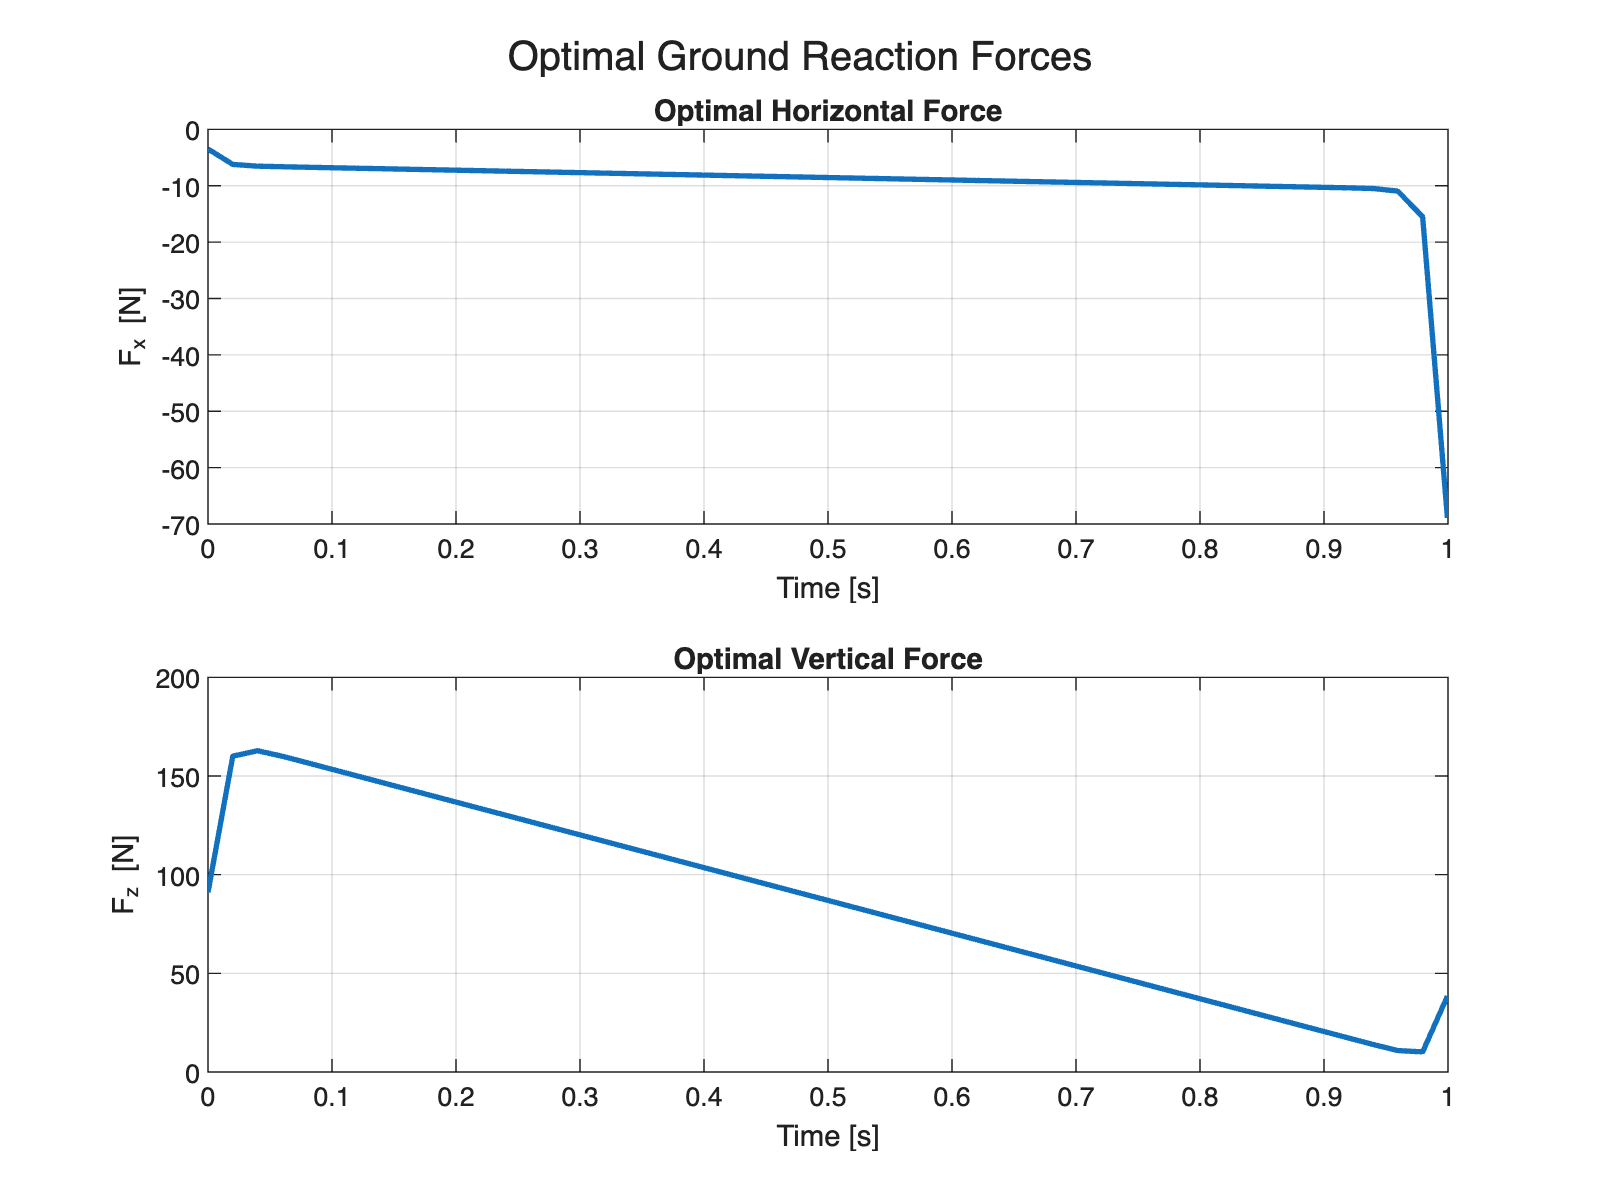


t_vec = (0:k-1) * dt_ctrl;
figure();

% SLIP trajectory
subplot(2,3,1);
plot(state_history(:,1), state_history(:,2), 'b-', 'LineWidth', 2); hold on;
plot(Xout(1,:), Xout(2,:), 'r--', 'LineWidth', 1.5);
xlabel('x [m]'); ylabel('z [m]');
title('2-leg SLIP Trajectory');
legend('Simulated SLIP', 'Optimal Plan', 'Location', 'best');
grid on; axis equal;

% X position
subplot(2,3,2);
plot(t_vec, state_history(:,1), 'b-', 'LineWidth', 2); hold on;
plot(tout, Xout(1,:), 'r--', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('x [m]');
title('Horizontal Position');
legend('SLIP Sim', 'Optimal');
grid on;

% Z position
subplot(2,3,3);
plot(t_vec, state_history(:,2), 'b-', 'LineWidth', 2); hold on;
plot(tout, Xout(2,:), 'r--', 'LineWidth', 1.5);
yline(p.l0, 'k:', 'Rest Height');
xlabel('Time [s]'); ylabel('z [m]');
title('Vertical Position');
legend('SLIP Sim', 'Optimal', 'l_0');
grid on;

% Velocities
subplot(2,3,4);
plot(t_vec, state_history(:,3), 'b-', 'LineWidth', 2); hold on;
plot(t_vec, state_history(:,4), 'r-', 'LineWidth', 2);
xlabel('Time [s]'); ylabel('Velocity [m/s]');
title('COM Velocities');
legend('v_x', 'v_z');
grid on;

% Leg lengths
subplot(2,3,5);
plot(t_vec, state_history(:,5), 'b-', 'LineWidth', 2); hold on;
plot(t_vec, state_history(:,9), 'r-', 'LineWidth', 2);
yline(p.l0, 'k--', 'Rest Length');
xlabel('Time [s]'); ylabel('Length [m]');
title('Leg Lengths');
legend('Left', 'Right', 'l_0');
grid on;

% Leg angles
subplot(2,3,6);
plot(t_vec, rad2deg(state_history(:,6)), 'b-', 'LineWidth', 2); hold on;
plot(t_vec, rad2deg(state_history(:,10)), 'r-', 'LineWidth', 2);
xlabel('Time [s]'); ylabel('Angle [deg]');
title('Leg Angles (from horizontal)');
legend('Left', 'Right');
grid on;

sgtitle('BDX Droid 2D SLIP Jump with Direct Collocation');

% ADDED: Plot optimal forces
figure('Position', [100 100 800 600]);
subplot(2,1,1);
plot(tout, Uout(1,:), 'LineWidth', 2);
xlabel('Time [s]'); ylabel('F_x [N]');
title('Optimal Horizontal Force');
grid on;

subplot(2,1,2);
plot(tout, Uout(2,:), 'LineWidth', 2);
xlabel('Time [s]'); ylabel('F_z [N]');
title('Optimal Vertical Force');
grid on;

sgtitle('Optimal Ground Reaction Forces');



function dX = dynamics_SLIP(X,U,p)
    % Calculates time derivative for states [x;z]

    M_tot = sum(p.M);
    g = p.g;
    Fx = U(1);
    Fz = U(2);

    ddx = Fx / M_tot; % point mass
    ddz = (Fz / M_tot) - g;

    dX = [X(3); X(4); ddx; ddz];
end


% Not used in control loop but can be used for initial state setup and
% logging and visualization for on the full model usage.
function rs2DSLIP = init2DSLIPState(rs,p)

    rs2DSLIP.x = rs.qb(1);
    rs2DSLIP.z = rs.qb(2);
    rs2DSLIP.dx = rs.dqb(1);
    rs2DSLIP.dz = rs.dqb(2);
    
    for i = 1:2
  
        dx = rs2DSLIP.x - rs.pf(i,1);
        dz = rs2DSLIP.z - rs.pf(i,2);
        rs2DSLIP.legs(i).length = sqrt(dx^2 + dz^2);
        rs2DSLIP.legs(i).angle = atan2(dz,dx); % Angle from foot to COM (z axis is up)
        rs2DSLIP.legs(i).dlength = 0;
        rs2DSLIP.legs(i).dangle = 0;
        rs2DSLIP.legs(i).footPos = rs.pf(i,:)';

        % State Transition Flags and History
        rs2DSLIP.legs(i).inStance = false; % start in flight phase
        rs2DSLIP.legs(i).prevLength = rs2DSLIP.legs(i).length;
        rs2DSLIP.legs(i).stance_start_time = 0; % Keep track of stance time

        % Fixed touchdown angle (vertical stance)
        rs2DSLIP.legs(i).touchdown_angle = rs2DSLIP.legs(i).angle;
    end

    % Global controller state
    rs2DSLIP.g = p.g;
    rs2DSLIP.M = sum(p.M); % Total mass
end

function rs2DSLIP = update2DSLIPState(rs2DSLIP,p, dt,k)
    Fx_tot = 0;
    Fz_tot = -rs2DSLIP.M * rs2DSLIP.g; % Gravity
    active_leg_idx = 0;
    
    for i = 1:2
        % Update Leg kinematics
        dx_com_foot = rs2DSLIP.x - rs2DSLIP.legs(i).footPos(1);
        dz_com_foot = rs2DSLIP.z - rs2DSLIP.legs(i).footPos(2);

        new_length = sqrt(dx_com_foot^2 + dz_com_foot^2);
        new_angle = atan2(dz_com_foot,dx_com_foot);

        % Updating values for legs
        rs2DSLIP.legs(i).dlength = (new_length - rs2DSLIP.legs(i).prevLength) / dt;
        rs2DSLIP.legs(i).length = new_length;
        rs2DSLIP.legs(i).angle = new_angle;
        rs2DSLIP.legs(i).prevLength = new_length; 

        % SLIP State Transitions and Force calculations
        % Flight to Stance Transition

        if (rs2DSLIP.legs(i).inStance == false) && ...
           (rs2DSLIP.legs(i).length <= p.l0 + 1e-4) && ...
           (rs2DSLIP.dz < 0)

            rs2DSLIP.legs(i).inStance = true;
            rs2DSLIP.legs(i).stance_start_time = k * dt;

            % Set the foot position based on the fixed angle and target
            % length l0
            % Foot placed directly COM at a distance l0

            %leg_angle_at_touchdown = rs2DSLIP.legs(i).touchdown_angle;
            rs2DSLIP.legs(i).footPos(1) = rs2DSLIP.x - p.l0 * cos(new_angle);
            rs2DSLIP.legs(i).footPos(2) = 0; % grond z = 0
            active_leg_idx = i;

        end

        % Stance phase dynamics
        if (rs2DSLIP.legs(i).inStance == true)
            active_leg_idx = i;

            % Stance forces
            Fspringleg = p.k*(p.l0 - rs2DSLIP.legs(i).length);
            Fdamp_mag = -p.c * rs2DSLIP.legs(i).dlength;
            Fleg_mag = Fspringleg + Fdamp_mag;

            Fx = Fleg_mag * cos(rs2DSLIP.legs(i).angle);
            Fz = Fleg_mag * sin(rs2DSLIP.legs(i).angle);
            Fx_tot = Fx_tot + Fx;
            Fz_tot = Fz_tot + Fz;
            
            % Stance to Flight Transition
            % Leg returns to resting length (l0) and is dangle > 0
            if (rs2DSLIP.legs(i).length >= p.l0) && (rs2DSLIP.legs(i).dlength > 0)
                rs2DSLIP.legs(i).inStance = false;

                % Reset the stance leg's foot position (floating now)
                rs2DSLIP.legs(i).footPos(2) = -100; % Off the ground 
            end
        end

    end


    % Integrate COM Dynamics (Forward Euler)
    rs2DSLIP.dx = rs2DSLIP.dx + dt * Fx_tot / rs2DSLIP.M;
    rs2DSLIP.dz = rs2DSLIP.dz + dt * Fz_tot / rs2DSLIP.M;
    rs2DSLIP.x = rs2DSLIP.x + dt * rs2DSLIP.dx;
    rs2DSLIP.z = rs2DSLIP.z + dt * rs2DSLIP.dz;
    

    if rs2DSLIP.z < p.l0 && active_leg_idx == 0
        rs2DSLIP.z = p.l0;
        
        if rs2DSLIP.dz < 0
            rs2DSLIP.dz = 0;
        end
    end

end




% LQR or Task Space Controller 
% Adjust this later
function [tau, ddq, F] = Task_Space_C(tsc, rs, rsDes, p)

% torso
Kpt = diag([0 100 80]);
Kdt = diag([5 5 10]);

dvTorDes = Kpt * (rsDes.ptor - rs.ptor) + Kdt * (rsDes.vtor - rs.vtor);

Atask = rs.Jtor;
Atask = diag(p.Q_tor) * Atask;
btask = rs.dJtordq - dvTorDes;
btask = diag(p.Q_tor) * btask;

% foot
Kpf = diag(repmat([500 800], [1,2]));
Kdf = diag(repmat([5 5], [1,2]));

dvFootDes = Kpf * (rsDes.pf - rs.pf) + Kdf * (rsDes.vf - rs.vf);

Atask = [Atask; diag(p.Q_f) * rs.Jf];
btask = [btask; diag(p.Q_f) * (rs.dJfdq - dvFootDes)];

% joint
Kp_j = diag(5 * [1 1 1 1]);
Kd_j = diag(1 * [1 1 1 1]);

ddqDes = Kp_j * (rsDes.qj - rs.qj) + Kd_j * (rsDes.dqj - rs.dqj);

Q_ddq = diag(0.1 * [1 1 1 1]);
for i_leg = 1:2
    idx = (i_leg-1) * 2 + (1:2);
    if rs.ifStance(i_leg)
        Q_ddq(idx,idx) = zeros(2);
    end
end

% Adjust for TSC
[tau, ddq, F] = tsc(rs.q, rs.dq, Atask, btask, rs.ifStance);

tau = full(tau);
ddq = full(ddq);
F = full(F);

end

function out = hatMap(in)
out = [0 -in(3) in(2);
       in(3) 0 -in(1);
       -in(2) in(1) 0];
end

function FK_FD_droid()
syms q [13,1] real
syms dq [13,1] real

syms g [1,1] real

syms l_hip_roll l_hip_pitch l_thigh l_shin l_foot real
syms M_trunk M_thigh M_shin M_foot real % Mass
syms I_trunk I_thigh I_shin I_foot real % Moment of Inertia - resistance to rotation

l = [l_hip_roll; l_hip_pitch; l_thigh; l_shin; l_foot];
M = [M_trunk; M_thigh; M_shin; M_foot]; 
I = [I_trunk; I_thigh; I_shin; I_foot]; 

params = [g;l;M;I];

N = 13;

rot = @(x)[cos(x) sin(x); -sin(x) cos(x)];

T01 = [rot(q3) [q1; q2]; 0 0 1];

% Left Leg (hmt are always 3x3 - we are in planar motion so only x z)
T12L = [eye(2) [0; 0]; 0 0 1];

T23L = [eye(2) [0; -l_hip_roll]; 0 0 1];

T34L = [rot(q6) [0; 0]; 0 0 1];

T45L = [eye(2) [0; -l_thigh]; 0 0 1];

T56L = [rot(q7) [0; 0]; 0 0 1];

T67L = [eye(2) [0; -l_shin]; 0 0 1];

T78L = [rot(q8) [0; 0]; 0 0 1];

T89L = [eye(2) [0; -l_foot]; 0 0 1];

T09L = T01 * T12L * T23L * T34L * T45L * T56L * T67L * T78L * T89L;
pf_L = T09L(1:2, 3);


% Right Leg
T12R = [eye(2) [0; 0]; 0 0 1];

T23R = [eye(2) [0; -l_hip_roll]; 0 0 1];

T34R = [rot(q11) [0; 0]; 0 0 1];

T45R = [eye(2) [0; -l_thigh]; 0 0 1];

T56R = [rot(q12) [0; 0]; 0 0 1];

T67R = [eye(2) [0; -l_shin]; 0 0 1];

T78R = [rot(q13) [0; 0]; 0 0 1];

T89R = [eye(2) [0; -l_foot]; 0 0 1];

T09R = T01 * T12R * T23R * T34R * T45R * T56R * T67R * T78R * T89R;
pf_R = T09R(1:2, 3);

pf = [pf_R; pf_L];
Jf = jacobian(pf, q);
dJfdq = reshape(jacobian(Jf(:),q) * dq, size(Jf)) * dq;

matlabFunction(pf, Jf, dJfdq, "File","fcn_foot_p_J_dJdq.m", "Vars",{q, dq, l})

% Torso kinematics
ptor = [T01(1:2,3); q3];
Jtor = jacobian(ptor, q);
dJtordq = reshape(jacobian(Jtor(:),q) * dq, size(Jtor)) * dq;

matlabFunction(ptor, Jtor, dJtordq, "File","fcn_torso_p_J_dJdq.m", "Vars",{q, dq, l})

p_trunk = T01(1:2,3); % floating base position is defined as trunk (entire rigid upper body) com (can add offset l_trunk/2)

% Left leg - COM (Center of Mass) (uniform mass distribution)
T0thighmidL = T01 * T12L * T23L * T34L * T45L;
pthighL = T0thighmidL(1:2,3) - [0; l_thigh/2];

T0shinmidL = T0thighmidL * T56L * T67L;
pshinmidL = T0shinmidL(1:2,3) - [0; l_shin/2];

T0footmidL = T0shinmidL * T78L * T89L;
pfootmidL = T0footmidL(1:2,3) - [0; l_foot/2];


% Right leg - COM (Center of Mass)so
T0thighmidR = T01 * T12R * T23R * T34R * T45R;
pthighR = T0thighmidR(1:2,3) - [0; l_thigh/2];

T0shinmidR = T0thighmidR * T56R * T67R;
pshinmidR = T0shinmidR(1:2,3) - [0; l_shin/2];

T0footmidR = T0shinmidR * T78R * T89R;
pfootmidR = T0footmidR(1:2,3) - [0;l_foot/2];

pcom = [p_trunk, pthighL, pshinmidL, pfootmidL, pthighR, pshinmidR, pfootmidR];
pcom = simplify(pcom);
vcom = reshape(jacobian(pcom(:),q) * dq, size(pcom));

%% Mass and Inertia matrix
M_ = [M_trunk M_thigh M_shin M_foot M_thigh M_shin M_foot]';
I_ = [I_trunk I_thigh I_shin I_foot I_thigh I_shin I_foot]';
PE = pcom(2,:) * M_ * g;

w_ = [dq3 dq3+dq6+dq7+dq8 dq3+dq6+dq7+dq8 dq3+dq11+dq12+dq13 dq3+dq11+dq12+dq13]';

KE = sym(0);
for ii = 1:5
    KE = KE + 0.5 * vcom(:,ii)' * M_(ii) * vcom(:,ii);
    KE = KE + 0.5 * w_(ii)' * I_(ii) * w_(ii);
end

G = jacobian(PE, q).';
H = simplify(hessian(KE,dq));

syms C [N, N] real
for k = 1:N
    for j = 1:N
        C(k,j) = 0;
        for i = 1:N
            xkji = jacobian(H(k,j),q(i));
            xkij = jacobian(H(k,i),q(j));
            xijk = jacobian(H(i,j),q(k));
            C(k,j) = C(k,j) + 1/2 * (xkji+xkij-xijk) * dq(i);
        end
    end
end

bias = C * dq + G;

matlabFunction(H, bias, 'File', 'fcn_droid_Mass_bias', 'Vars',{q,dq,params})

end
